**Лабораторная работа №1**

**Исследование однофазного неуправляемого двухполупериодного выпрямителя**

**Цель работы: **Исследование на компьютерной модели однофазного неуправляемого двухполупериодного выпрямителя при работе на активно-индуктивную нагрузку.

**Содержание: **Исследование внешней и энергетических характеристик однофазного двухполупериодного выпрямителя при работе на активно-индуктивную нагрузку.

**Теория работы преобразователя: **На электрическом подвижном составе для преобразования однофазного переменного напряжения в постоянное, необходимое для питания тяговых двигателӗи в моторном режиме или обмоток возбуждения при электрическом торможении, применяются однофазные схемы выпрямления: - с нулево̆и точко̆и вторично̆и обмотки трансформатора; - мостовая. Дня питания тяговых двигателӗи используют мостовую схему, для питания обмоток возбуждения - схему с нулево̆и точко̆и, Работа выпрямителя и его технико-экономические показатели определяются схемо̆и выпрямления, от которо̆и зависят: - форма криво̆и выпрямленного напряжения; - форма криво̆и тока первичного источника; - внешняя характеристика; - коэффициент мощности выпрямителя X; - коэффициент полезного дӗиствия h. 

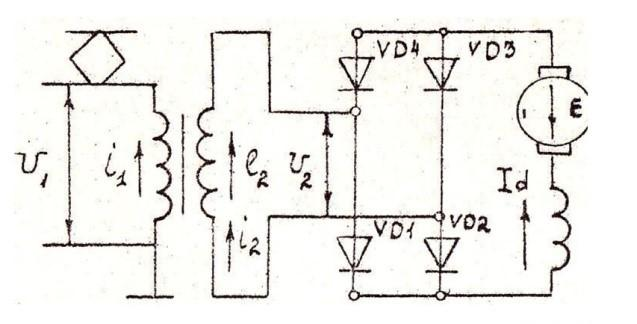

                                Рисунок 1 - Схема мостового выпрямителя 

Если Ld = ¥ , то остается постоянным ток нагрузки и при достижении напряжения на вторично̆и обмотке нулевого значения за счет анергии, накопленно̆и в индуктивности анодно̆и цепи, ток вторично̆и обмотки i2 трансформатора будет протекать в том же направлении, например через VD1 и VD3 (рис.1). При изменении полярности напряжения вторично̆и обмотки трансформатора е2 ток и напряженйи в нӗи будут направлены встречно. Это приведет к уменьшению i2 . Избыток тока нагрузки (id – i2) будет протекать через диоды VD1, VD4, а также VD2, VD 3. Таким образом, вторичная обмотка трансформатора оказывается замкнуто̆и накоротко до тех пор, пока ток вторично̆и обмотки i2 под дӗиствием е2, не изменит своего направления и не достигнет величины Id. После этого диоды VD1 и VD3 запираются, а токи i2 и Id будут протекать через диоды VD2, VD4. На этом процесс короткого замыкания заканчивается и к нагрузке прикладывается напряжение вторично̆и обмотки трансформатора (рис.2).

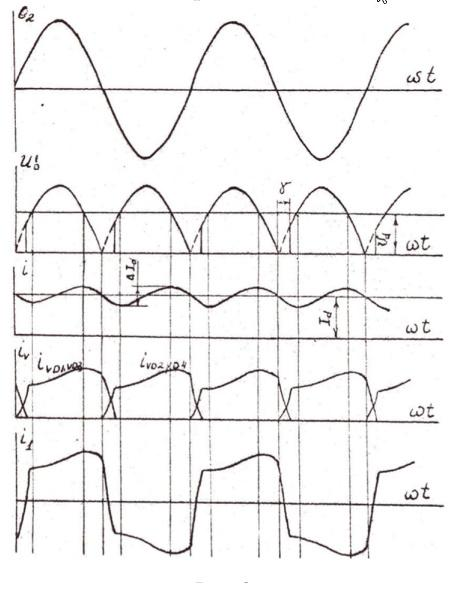

Рисунок 2 - Диаграммы мостового выпрямителя 

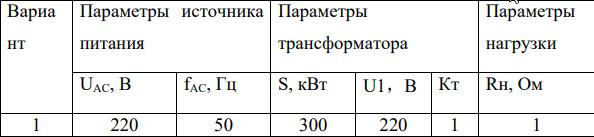

      Таблица 1 - Исходные данные 

**Схема компьютерной модели **

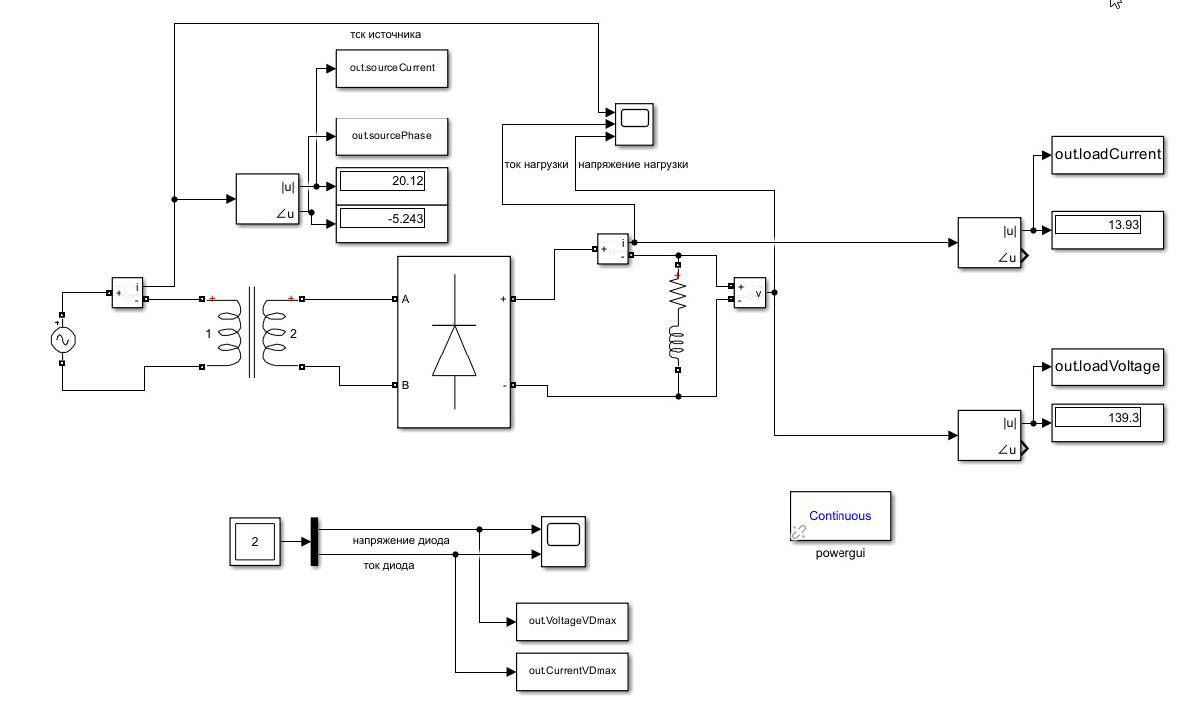

Рисунок 3 - Компьютерная модель

**Виртуальная лабораторная установка для исследованйи, предусмотренных содержанием работы содержит: **

• источник синусоидального напряжения (AC Voltage); 

• однофазны̆и трансформатор (Transformer); 

• однофазны̆и диодный мост (Universal Bridge);

 • активно-индуктивную нагрузку (R, L); 

• обратный диод (Diode);

• измерители мгновенных токов в источнике питания (I1) и нагрузке (I Load); 

• измеритель мгновенного напряжения на нагрузке (U Load);

**Зададим параметры источника напряжения**

source.voltage = 220;
source.freq = 50;

**Зададим параметры трансформатора**

transparam.power = 300 * 10^3;
transparam.volt1wing = 220;
K_T = 1;
transparam.volt2wing = transparam.volt1wing * K_T;

**Зададим параметры нагрузки**

load.Res = 1;
load.Ind = load.Res * 0.01;

**Формируем массивы для снятия параметров измерений в таблицу **

**(инициализируя переменные и присваивая пустой массив)**

r_l = [];
i_l = [];
I_n = [];
U_n = [];
I_1max = [];
Phi_1max = [];
U_VDmax = [];
I_VDmax = [];
U_1max = source.voltage * ones(1, 10);
f_1 = source.freq * ones(1, 10);
S_1 = [];
P_1 = [];
P_n = [];

**С помощью цикла производим итерацию и расчет по формуле с шагом изменения сопротивления 1 Ом, добавляем значения в вышесозданные массивы каждую итерацию, рассчитываем параметры по формулам:**


$$S_{1}(1) = \frac {U_{1max} \cdot I_{1max}}  {2} $$



$$P_{1}(1) = S_{1}(1) \cdot cos(\phi)$$



$$P_н = U_н \cdot I_н$$


for i = 1:1:10
    load.Res = i;
    load.Ind = load.Res * 0.01;
    sim("lr1.slx");
    I_n(end+1) = ans.loadCurrent(end, 1);
    U_n(end+1) = ans.loadVoltage(end, 1);
    I_1max(end+1) = ans.sourceCurrent(end, 1);
    Phi_1max(end+1) = ans.sourcePhase(end, 1);
    r_l(end+1) = load.Res;
    i_l(end+1) = load.Ind;
    U_VDmax(end+1) = max(ans.VoltageVDmax);
    I_VDmax(end+1) = max(ans.CurrentVDmax);
    S_1(end+1) = U_1max(i) * I_1max(i) / 2;
    P_1(end+1) = S_1(i)*cos(Phi_1max(i)*pi/180);
    P_n(end+1) = U_n(i) * I_n(i);
end

**Переносим результаты моделирования в таблицу**

T = table(U_1max.',f_1.', r_l.',i_l.',I_n.',U_n.',I_1max.',Phi_1max.', U_VDmax.', I_VDmax.', S_1.', P_1.', P_n.');
T.Properties.VariableNames = ["U1max", "f1", "Rн", "Lн", "Iн","Uн","I1max","phi1max", "U_VDmax", "I_VDmax", "S1", "P1", "Pн"];
disp(T);

    U1max    f1    Rн     Lн       Iн        Uн      I1max     phi1max    U_VDmax     I_VDmax      S1        P1        Pн  
    _____    __    __    ____    ______    ______    ______    _______    ________    _______    ______    ______    ______

     220     50     1    0.01    133.15    133.15    173.51    -5.6754     0.14734    147.34      19086     18992     17728
     220     50     2    0.02    68.241    136.48    89.963     -5.425    0.075356    75.356       9896    9851.7    9313.6
     220     50     3    0.03     45.88    137.64    61.198  

**Строим осциллограммы напряжения и тока диодов моста:**

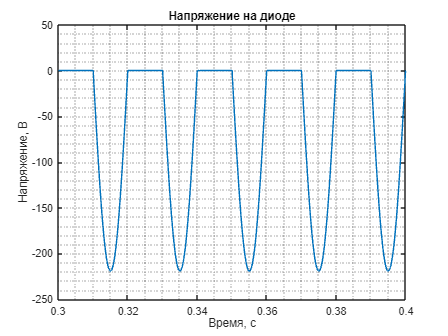

plot(ans.ScopeVD{1}.Values);
grid("minor");
xlabel('Время, с');
ylabel('Напряжение, В');
title('Напряжение на диоде');
xlim([0.3 0.4]);

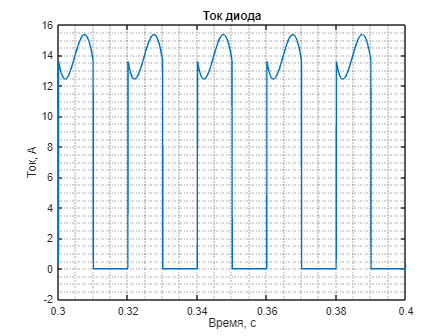


plot(ans.ScopeVD{2}.Values);
grid("minor");
xlabel('Время, с');
ylabel('Ток, А');
title('Ток диода');
xlim([0.3 0.4]);

Строим осциллограммы тока питания, тока нагрузки и напряжения на нагрузке

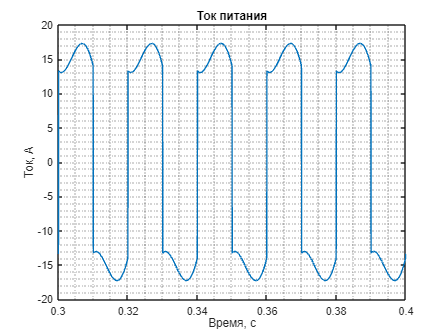

plot(ans.Scope{1}.Values);
grid("minor");
xlabel('Время, с');
ylabel('Ток, А');
title('Ток питания');
xlim([0.3 0.4]);

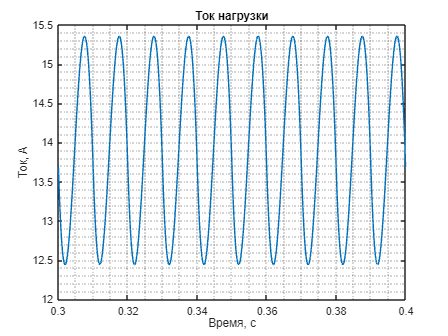

plot(ans.Scope{2}.Values);
grid("minor");
xlabel('Время, с');
ylabel('Ток, А');
title('Ток нагрузки');
xlim([0.3 0.4]);

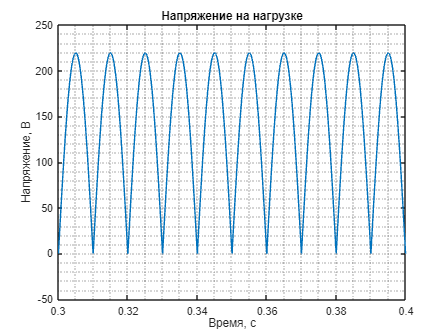

plot(ans.Scope{3}.Values);
grid("minor");
xlabel('Время, с');
ylabel('Напряжение, В');
title('Напряжение на нагрузке');
xlim([0.3 0.4]);

**Вывод: **

В ходе лабораторной работы мы исследовали работу однофазного неуправляемого двухполупериодного выпрямителя при работе на активно-индуктивную нагрузку. При повышении сопротивления и индуктивности нагрузки:

 • ток нагрузки уменьшается;

 • напряжение нагрузки увеличивается;

 • напряжение на выпрямителе остается неизменным;

 • ток выпрямителя уменьшается;

 • полная мощность, потребляемая выпрямителем от источника питания уменьшается;

 • активная мощность, потребляемая выпрямителем от источника питания уменьшается;

 • мощность в нагрузке умеьшается.